## Quadrature Rule - Ex. 9.1

clear all;
close all;
clc;

Consider:


$$I_1 = \int_0^1 x^3 dx = \frac{1}{4}$$


and


$$I_2 = \int_0^1 x^5 dx = \frac{1}{6}$$


f1 = @(x) x.^3;
f2 = @(x) x.^5;

a = 0;
b = 1;

### c. Compute the integral $I_1$ using the midpoint rule with 1 and 10 nodes and the composite trapezoidal rule with 2 and 10 nodes

Midpoint rule

I1mp1 = midpoint(a, b, f1)

I1mp1 = 0.1250

I1mp10 = cmidpoint(a, b, 10, f1)

I1mp10 = 0.2488

Trapezoidal rule

I2mp2 = ctrapezoidal(a, b, 2, f1)

I2mp2 = 0.3125

I2mp10 = ctrapezoidal(a, b, 9, f1)

I2mp10 = 0.2531

### d. Compute $I_1$ and $I_2$ with the composite Simpson rule with 3 and 7 nodes

With 3 nodes:

I1simp3 = csimpson(a, b, 1, f1)

I1simp3 = 0.2500

I2simp3 = csimpson(a, b, 1, f2)

I2simp3 = 0.1875

With 7 nodes:

I1simp7 = csimpson(a, b, 3, f1)

I1simp7 = 0.2500

I2simp7 = csimpson(a, b, 3, f2)

I2simp7 = 0.1669

### e. Estimate the number of nodes needed to compute $I_2$ with a tolerance of $10^{-3}$ using the composite trapezoidal and Simpson rule

Composite trapezoidal:

h_star_ct = sqrt(12 * 1e-3 / ((b-a) * 20));
m_star_ct = ceil((b-a) / h_star_ct)

m_star_ct = 41

 Composite Simpson:

h_star_cs = ((180 * 1e-3) / ((b-a) * 120))^(1/4);
m_star_cs = ceil((b-a) / (2*h_star_cs))

m_star_cs = 3

### f. Approximate the order of accuracy of the three composite methods

integr_m = zeros(10, 1);
integr_t = zeros(10, 1);
integr_s = zeros(10, 1);

for i = 0:9
  m = 2^i;
  integr_m(i+1) = cmidpoint(a, b, m, f2);
  integr_t(i+1) = ctrapezoidal(a, b, m, f2);
  integr_s(i+1) = csimpson(a, b, m, f2);
end

err_m = abs(1/6 - integr_m)

err_m =     0.1354
    0.0475
    0.0127
    0.0032
    0.0008
    0.0002
    0.0001
    0.0000
    0.0000
    0.0000


err_t = abs(1/6 - integr_t)

err_t =     0.3333
    0.0990
    0.0257
    0.0065
    0.0016
    0.0004
    0.0001
    0.0000
    0.0000
    0.0000


err_s = abs(1/6 - integr_s)

err_s =     0.0208
    0.0013
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



p_m = -diff(log(err_m)) / log(2)

p_m =     1.5106
    1.8998
    1.9760
    1.9941
    1.9985
    1.9996
    1.9999
    2.0000
    2.0000


p_t = -diff(log(err_t)) / log(2)

p_t =     1.7521
    1.9441
    1.9864
    1.9966
    1.9992
    1.9998
    1.9999
    2.0000
    2.0000


p_s = -diff(log(err_s)) / log(2)

p_s =     4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000
    4.0000


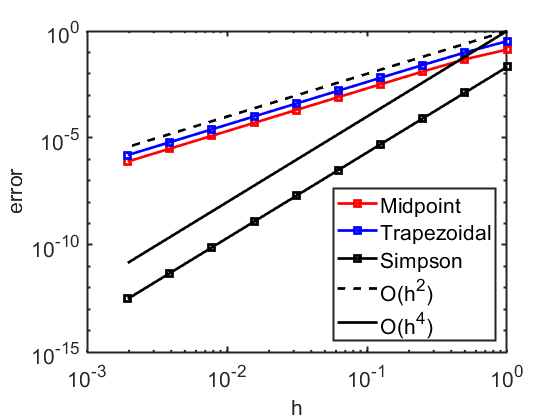


% As expected, the error decreases quadratically in h for both midpoint
% and trapezoidal rules. For Simpson rule instead, convergence is of fourth order in h.

% Graphical visualization of the order of accuracy.
h = 1./2.^[0:9]; % [1/1; 1/2; 1/4; ...; 1/2^9]
figure
loglog(h, err_m, 'rs-', 'LineWidth', 2)
hold on, box on
loglog(h, err_t, 'bs-', 'LineWidth', 2)
loglog(h, err_s, 'ks-', 'LineWidth', 2)
loglog(h, h.^2, 'k--', 'LineWidth', 2)
loglog(h, h.^4, 'k-', 'LineWidth', 2)
set(gca,'FontSize',16)
set(gca,'LineWidth',1.5)
xlabel('h','FontSize',16)
ylabel('error','FontSize',16)
leg = legend('Midpoint', 'Trapezoidal', 'Simpson', 'O(h^2)', 'O(h^4)', 'Location', 'SouthEast');
set(leg,'FontSize',16)
set(leg,'LineWidth',1.5)

### a. Implement the simple midpoint, trapezoidal and Simpson rule in three different functions

function res = midpoint(a, b, f)
    res = (b-a)*f((a+b)/2);
end

function res = trapezoidal(a, b, f)
    res = ((b-a)/2)*(f(a) + f(b));
end

function res = simpson(a, b, f)
    res = ((b-a)/6)*(f(a) + f(b) + 4*f((a+b)/2));
end

### b. Implement the composite version of the quadrature rules

function int = cmidpoint(a, b, m, f)
    x = linspace(a, b, m+1);
	int = 0;

	for i = 1:m
		int = int + midpoint(x(i), x(i+1), f);
    end
end

function int = ctrapezoidal(a, b, m, f)
    x = linspace(a, b, m+1);
	int = 0;

	for i = 1:m
		int = int + trapezoidal(x(i), x(i+1), f);
    end
end

function int = csimpson(a, b, m, f)
    x = linspace(a, b, m+1);
	int = 0;

	for i = 1:m
		int = int + simpson(x(i), x(i+1), f);
    end
end